# Introduction

Implementation of Spiliopoulos' inter-bank reserves model with networks. We increase the number of Banks, N, from 10 to 100 in order for the network effects to be more prevalent.


$$\mathrm{d}X_t^i = \frac{\theta_{i}}{N}\sum_{j=1}^{N} a_{i,j} \left(X_{t}^{j} - X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}W^{i}_{t}$$


# Baseline - Homogeneous Banks

Homogeneous banks ($N = 100, a = 1, \sigma = 1$), all-to-all coupling.

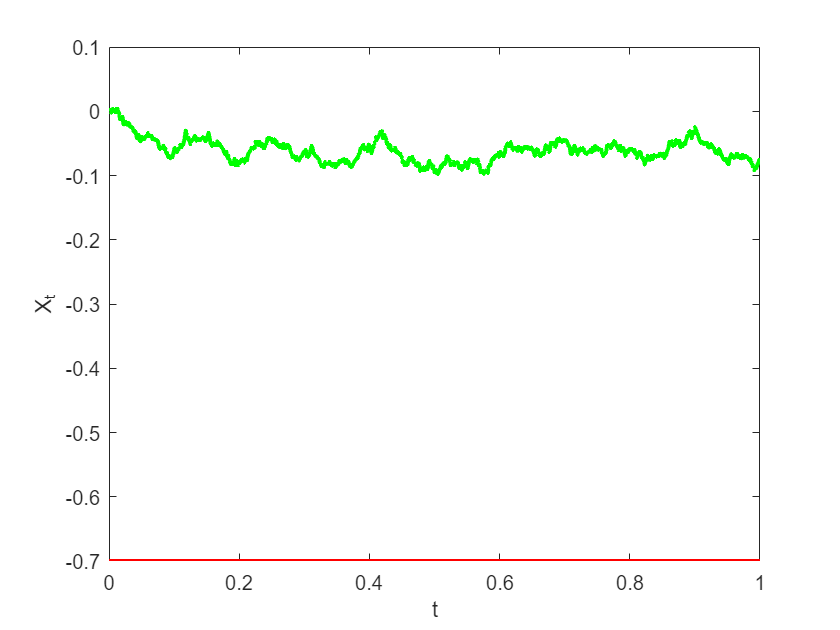

baseline = model(100, ones(100, 1), ones(100, 1));
baseline = baseline.sde_euler;
baseline.plot_trajectory(0);

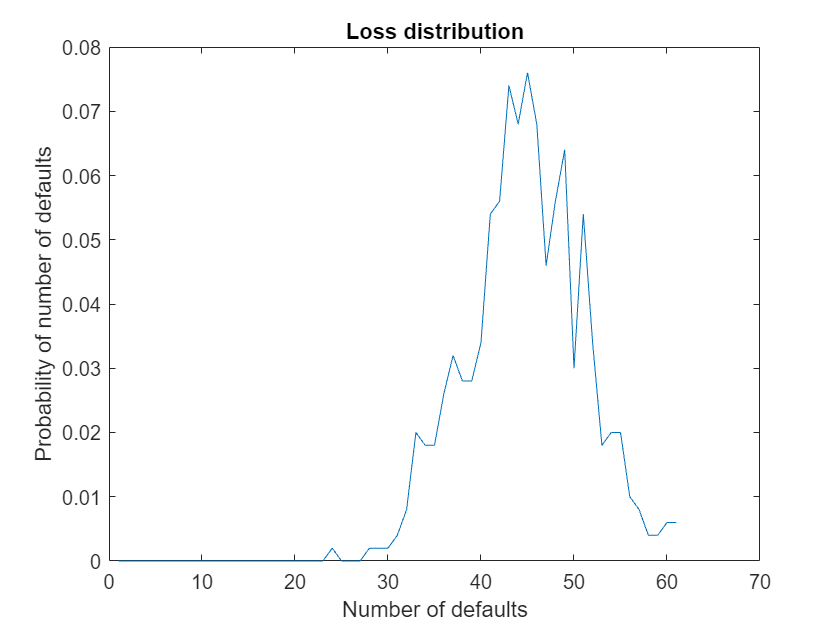

baseline.plot_loss

# Erdos Renyi

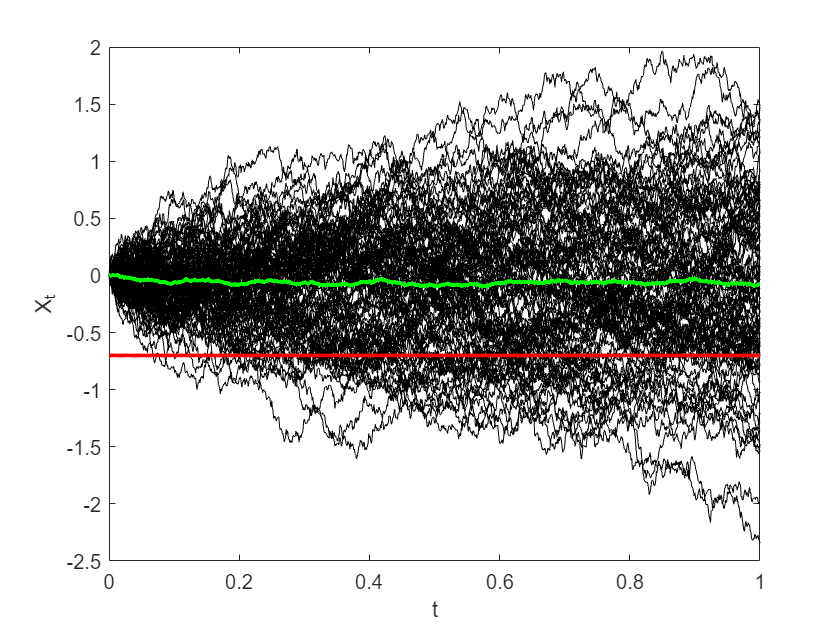

erdosrenyi = baseline.erdosrenyi(0.5);
erdosrenyi = erdosrenyi.network;
erdosrenyi = erdosrenyi.sde_euler;
erdosrenyi.plot_trajectory;

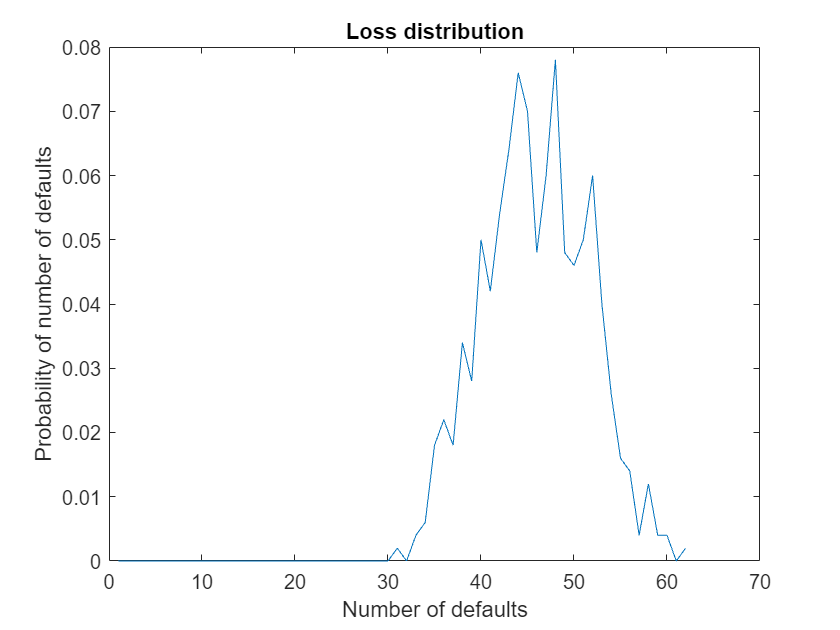

erdosrenyi.plot_loss;

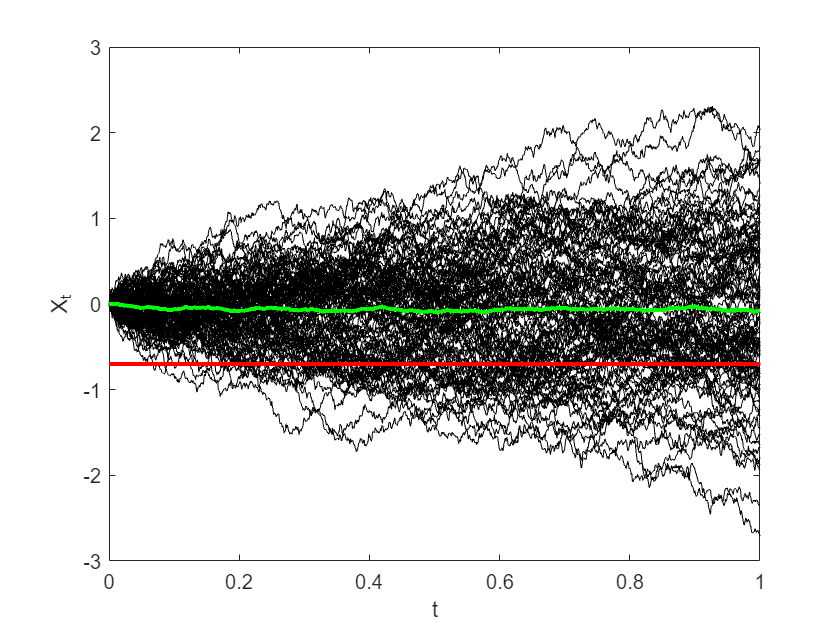

heterophily = baseline.heterophily(0.5);
heterophily = heterophily.sde_euler;
heterophily.plot_trajectory;

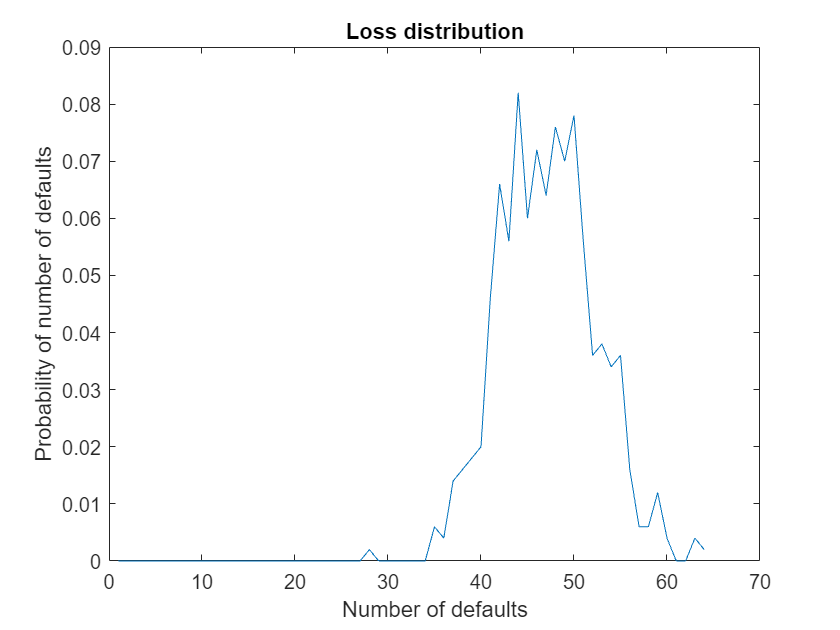

heterophily.plot_loss;

# Group A


$$\mathrm{d}X_t^i = \frac{\theta_{i}}{N}\sum_{j=1}^{N} a_{i,j} \left(X_{t}^{j} - X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}W^{i}_{t}$$


$(\theta, \sigma) = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$with ratios $\{0.2, 0.5, 0.3\}$.

Agents with small coefficients $a_i$ have large coefficients $\sigma_i$,while agents with large coefficients $a_i$ have small coefficients $\sigma_i$.

## Baseline

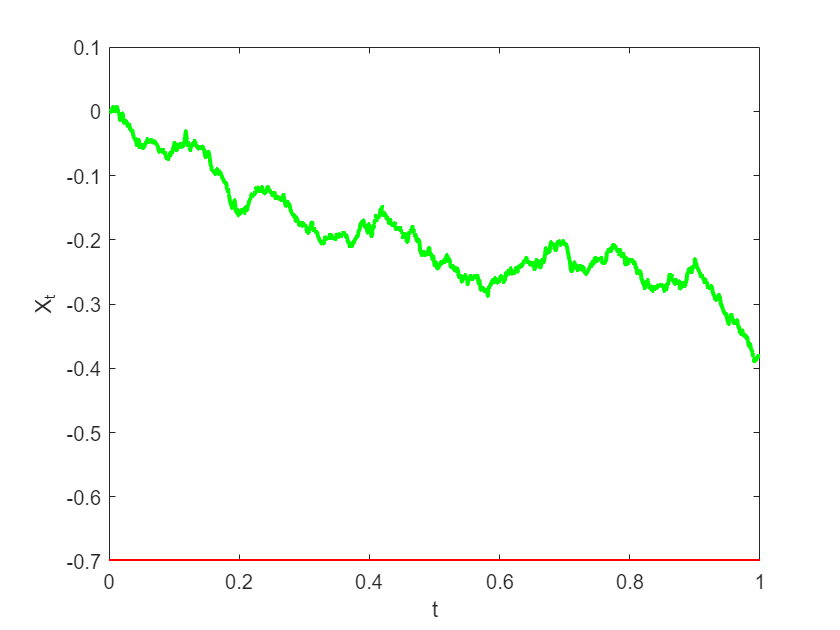

model_A = model(100, ...
    [repelem(1, 20, 1); repelem(10, 50, 1); repelem(100, 30, 1)], ...
    [repelem(2, 20, 1); repelem(1, 50, 1); repelem(0.5, 30, 1)] ...
    );
model_A = model_A.sde_euler;
model_A.plot_trajectory(0);

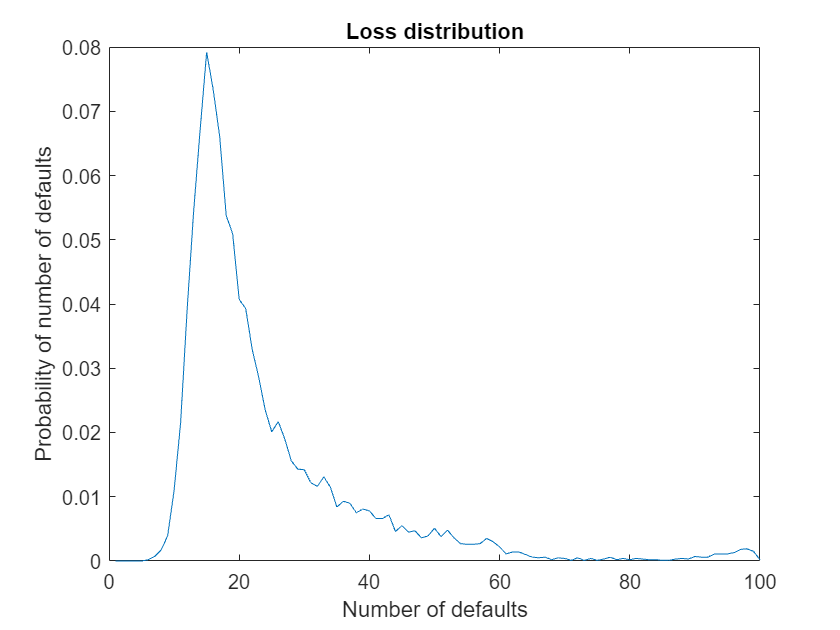

model_A.plot_loss(10000);

# Group A with networks

## Erdos-Renyi

We assume the adjacency matrix takes values


$$$$
a_{i,j}=
\begin{cases}
1 & \text{with probability } p \\
0 & \text{with probability } 1-p
\end{cases}
\quad \text{for } \quad i, j = 1, \dots, N
$$$$


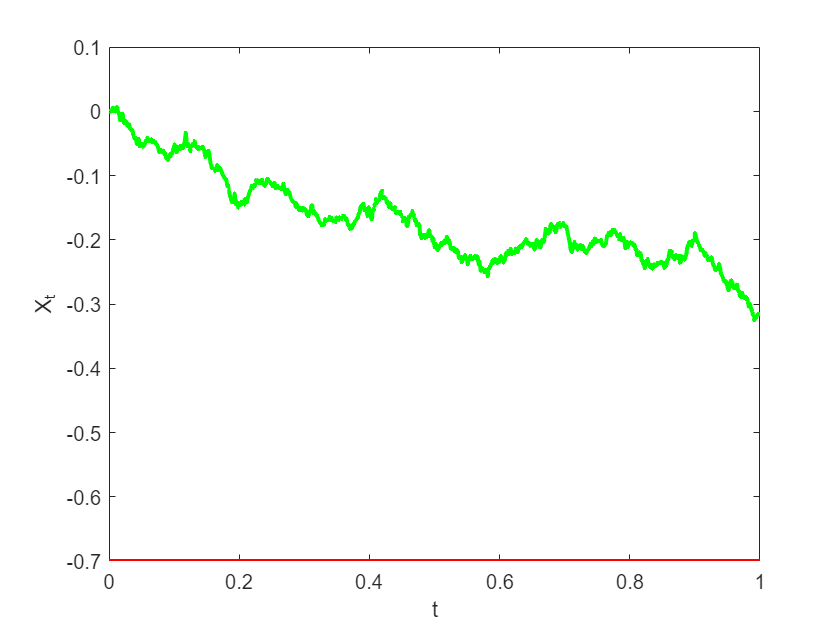

erdosrenyi_a = model_A.erdosrenyi(0.5);
erdosrenyi_a = erdosrenyi_a.network;
erdosrenyi_a = erdosrenyi_a.sde_euler;
erdosrenyi_a.plot_trajectory(0);

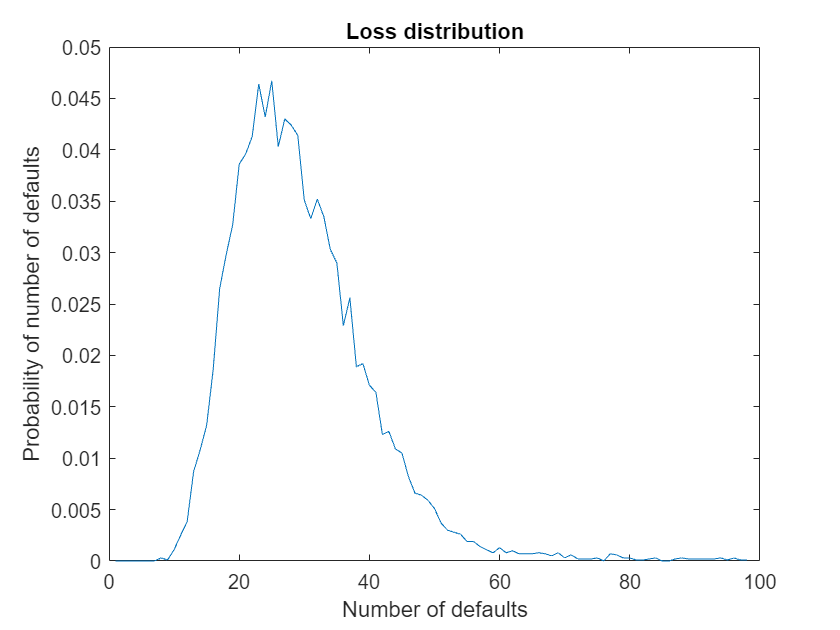

erdosrenyi_a.plot_loss(10000);

## Star

In a star-network, some banks are fully connected while others are sparsely connected

### Small banks fully-connected

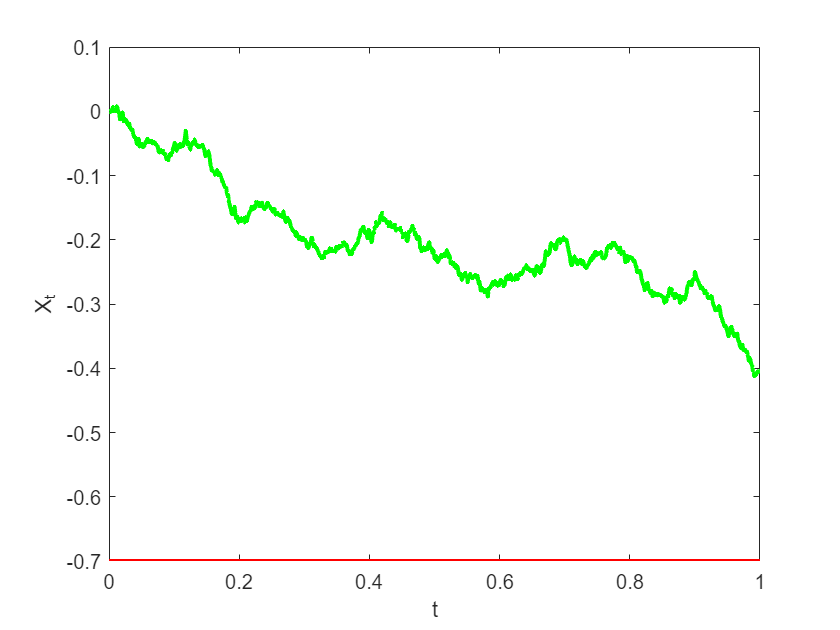

star_a_small = model_A.star(1, 20);
star_a_small = star_a_small.network;
star_a_small = star_a_small.sde_euler;
star_a_small.plot_trajectory(0);

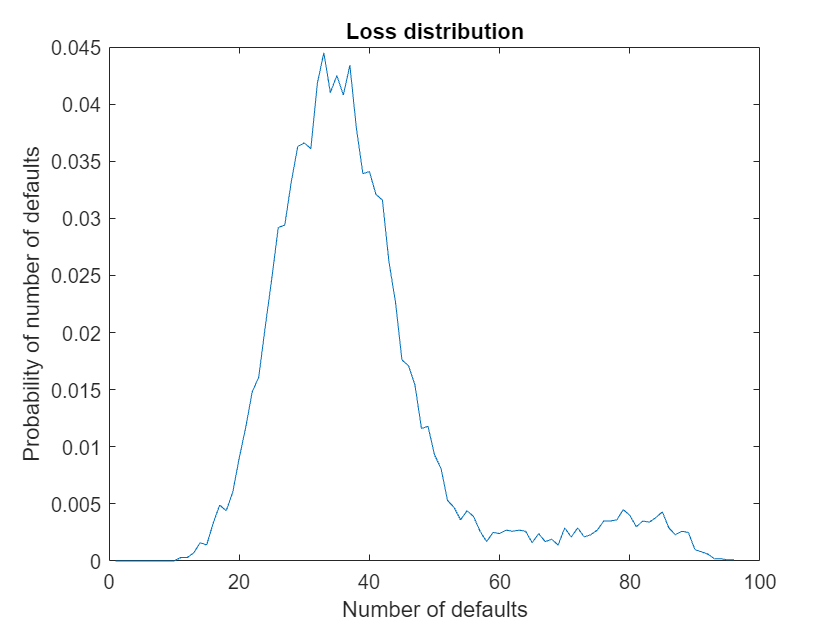

star_a_small.plot_loss(10000);

### Intermediate banks fully-connected

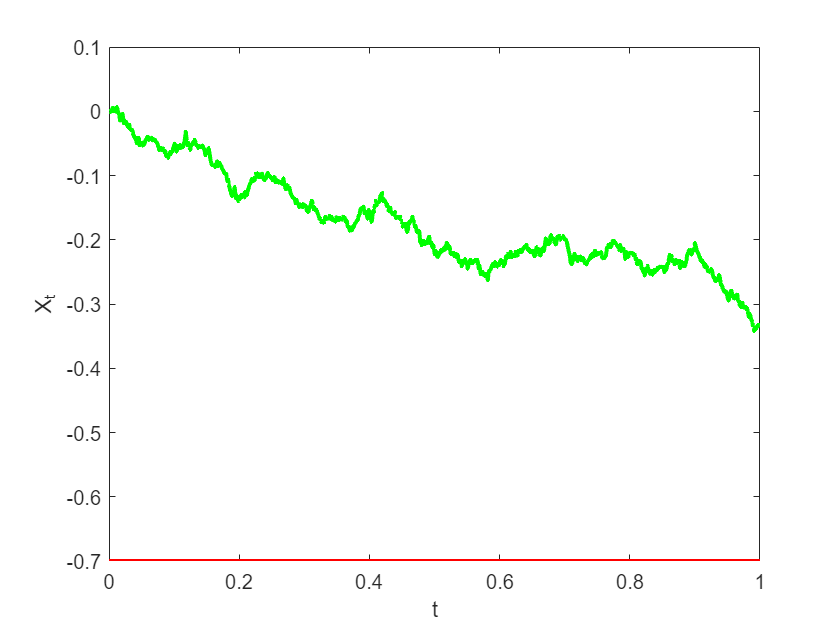

star_a_med = model_A.star(21, 70);
star_a_med = star_a_med.network;
star_a_med = star_a_med.sde_euler;
star_a_med.plot_trajectory(0);

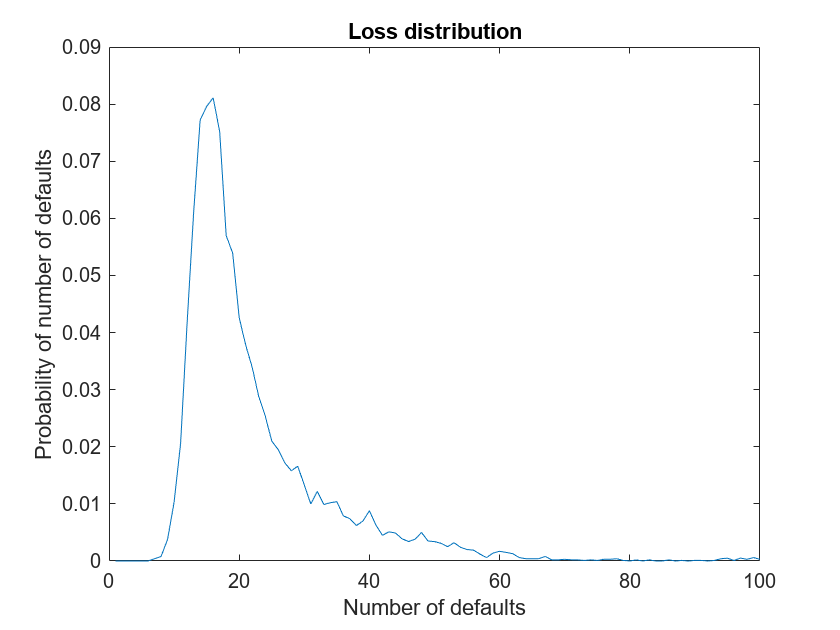

star_a_med.plot_loss(10000);

### Large banks fully-connected

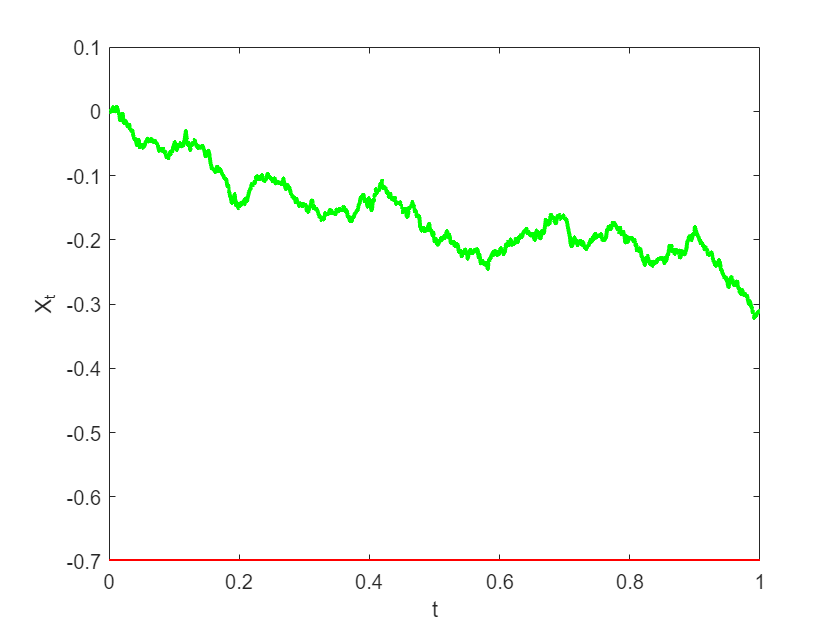

star_a_large = model_A.star(71, 100);
star_a_large = star_a_large.network;
star_a_large = star_a_large.sde_euler;
star_a_large.plot_trajectory(0);

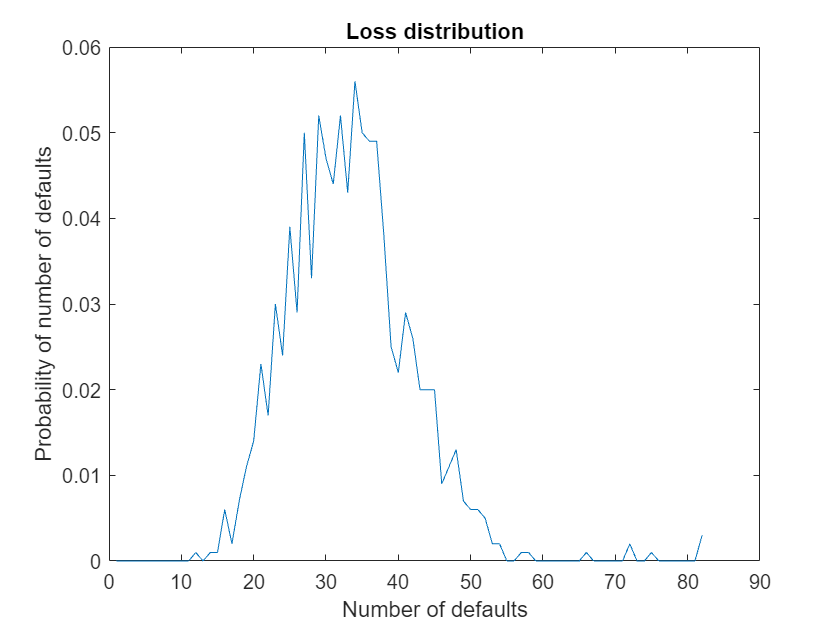

star_a_large.plot_loss(1000);

## Homophily

We assume that the adjacency matrix is of the form:


$$$$
a_{i,j}=
\begin{cases}
1, & \text{if } \quad |x_{i} - x_{j}| \leq \tau \\
0, & \text{if } \quad |x_{i} - x_{j}| > \tau
\end{cases}
\quad \text{for } \quad i, j = 1, \dots, N
$$$$


where $\tau$ denotes the radius of interactions - the maximum distance allowed between $x_{i}$ and $x_{j}$ for them to continue interacting with each other.

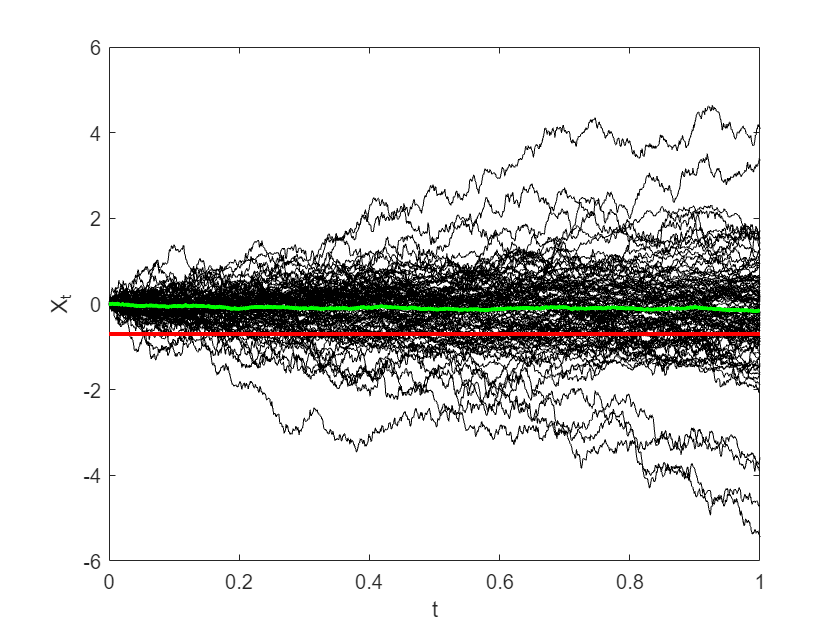

homophily_a = model_A.homophily(0.5);
homophily_a = homophily_a.sde_euler;
homophily_a.plot_trajectory;

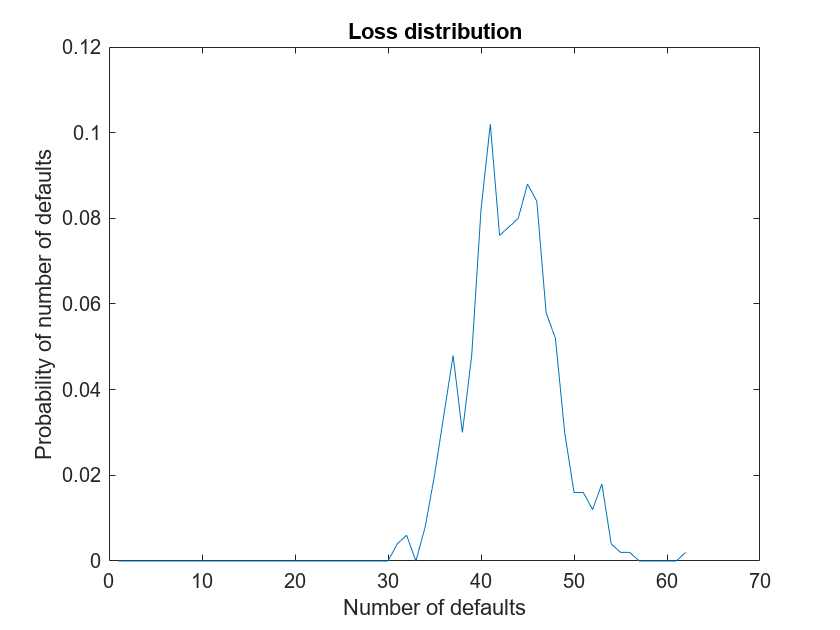

homophily_a.plot_loss;

## Heterophily

We assume that the adjacency matrix is of the form:

$$$
a_{i,j}=
\begin{cases}
1, & \text{if } \quad |x_{i} - x_{j}| > \tau \\
0, & \text{if } \quad |x_{i} - x_{j}| \leq \tau
\end{cases}
\quad \text{for } \quad i, j = 1, \dots, N, i \neq j
$$$, with $\{a_{i,i}\}_{i=1}^{N} = 1$.

where $\tau$ denotes the radius of interactions - the minimum distance allowed between $x_{i}$ and $x_{j}$ for them to continue interacting with each other. 


$$\tau = 0.2$$


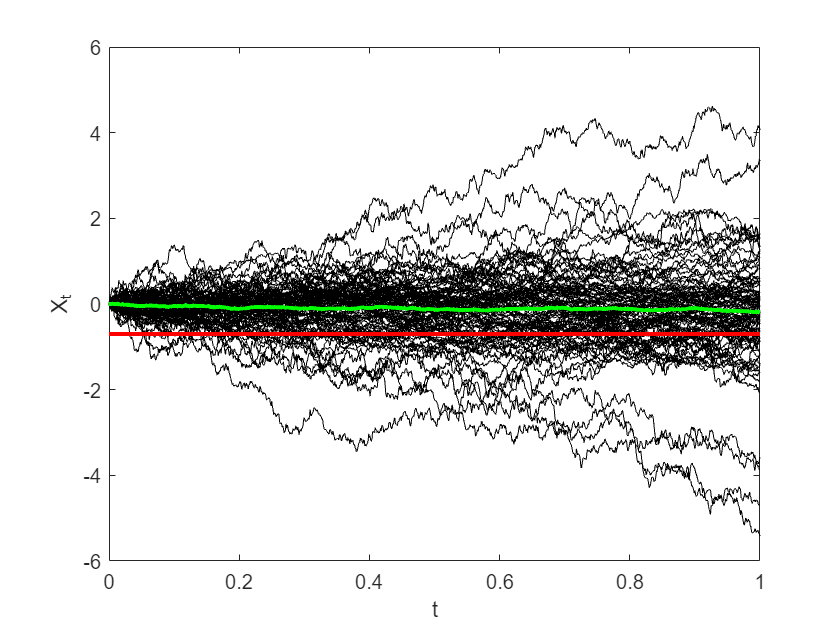

heterophily_a = model_A.heterophily(0.5);
heterophily_a = heterophily_a.sde_euler;
heterophily_a.plot_trajectory;

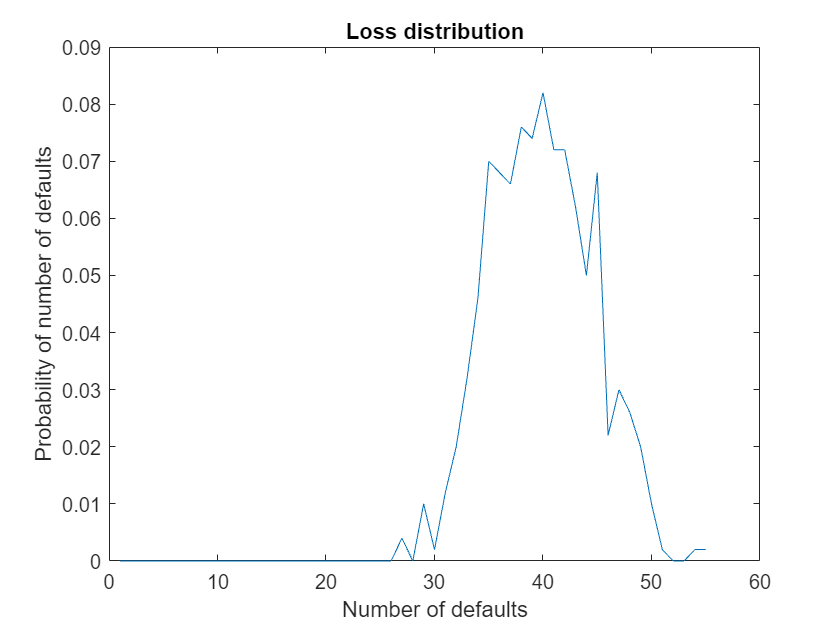

heterophily_a.plot_loss;